(4a)

figure(1);
sgtitle("PDF of regular die for different values of n");
N = [1, 2, 3, 10, 30, 100];
S = cumsum(rand(100, 10000) * 4 + 3);
for i = 1:6
    s = subplot(3, 2, i);
    title("x = " + N(i)); xlabel("Z_n"); ylabel("pdf");
    hold on;
    histogram(S(N(i), :) / N(i), 'Normalization', 'pdf');
end

(4b) Xi is a uniform continuous random variable. In class, we derived formulas for mean and standard deviation of these types of RVs. As the RV falls between 3 and 7, the mean of Xi is (3 + 7) / 2 = 5. The mean of the mean should therefore also be 5. Thus, the mean of Zn is 5. 

The variance formula is (b - a)^2 / 12 = 4^2 / 12 = 4 / 3, which is the variance of Xi. To find the variance of Zn, we use properties of variance. VAR(Zn) = VAR(sum(Xi) / n) = 1/n^2 * VAR(sum(Xi)) = 1/n^2 * n * VAR(Xi) since Xi are all i.i.d. This ends up being VAR(Xi) / n = 4/(3n). 

(4c)

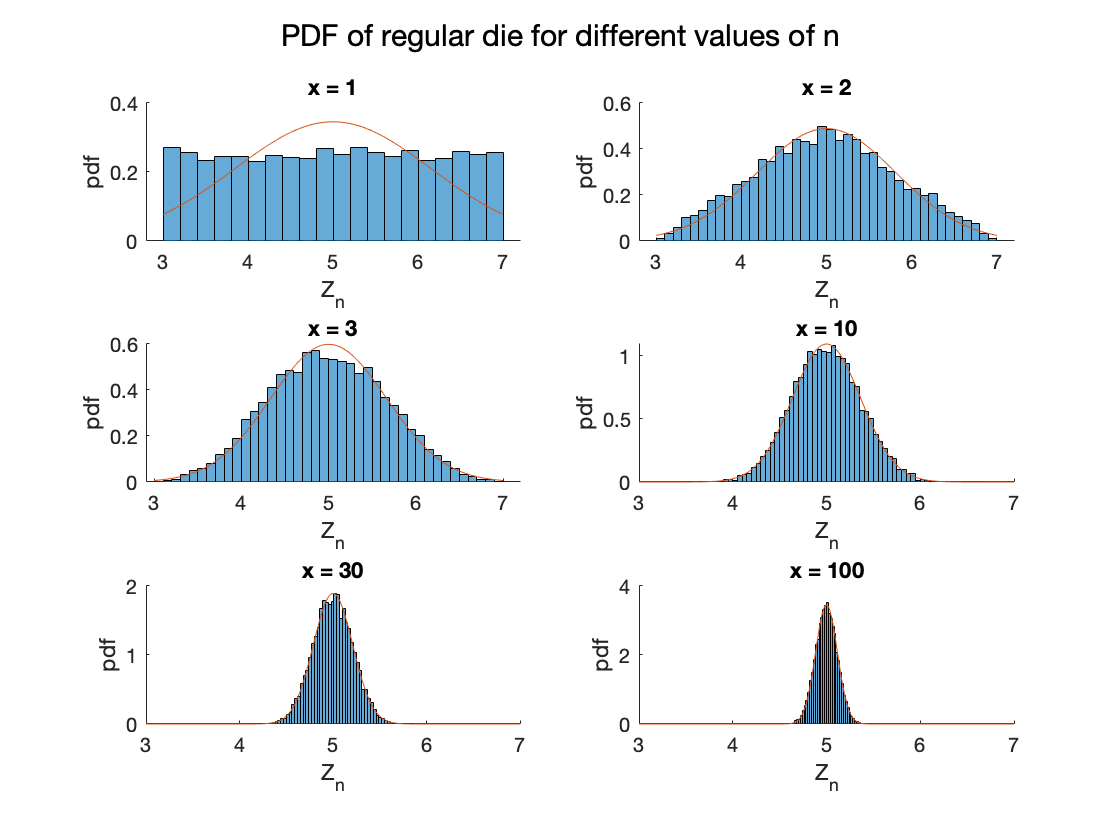

for i = 1:6
    x = (3:0.01:7);
    y = normpdf(x, 5, sqrt(4 / (3 * N(i))));
    s = subplot(3, 2, i);
    plot(x, y);
    hold off;
end

(4d)

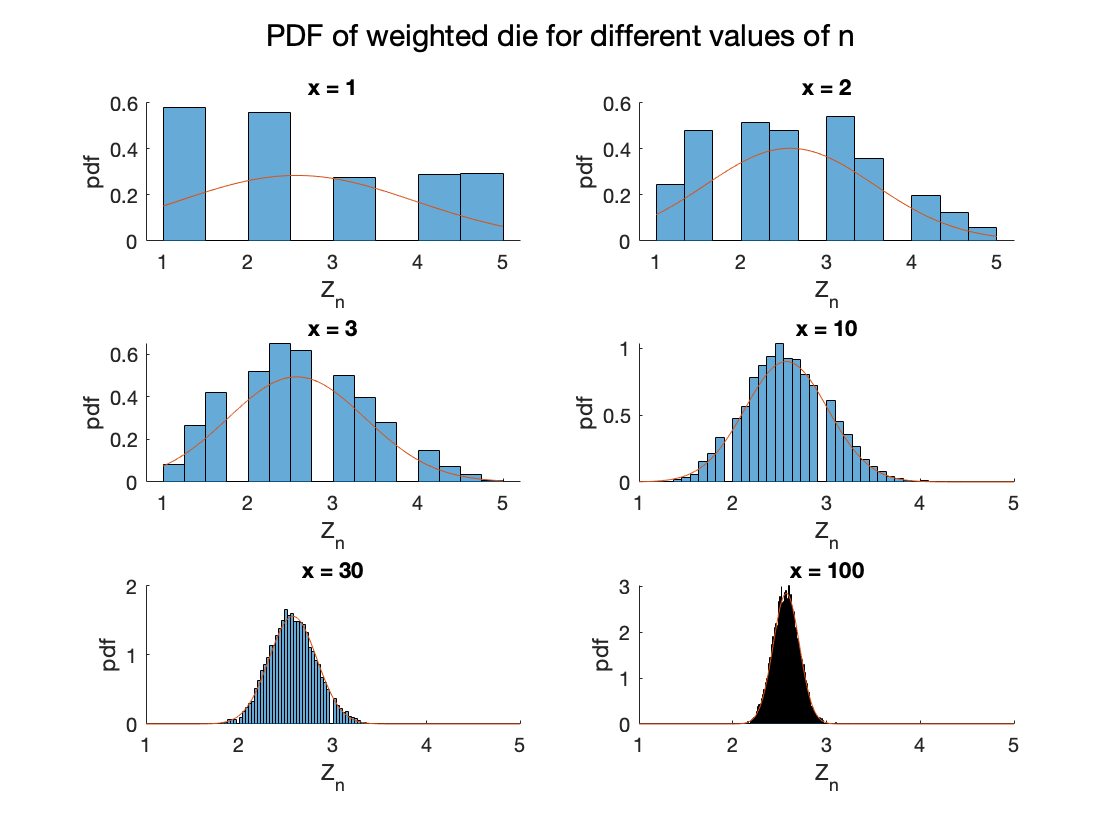

figure(2);
sgtitle("PDF of weighted die for different values of n");
N = [1, 2, 3, 10, 30, 100];
X = abs(floor(rand(100, 10000) * 7) - 2);
X(X == 0) = 5;
S = cumsum(X);
for i = 1:6
    s = subplot(3, 2, i);
    title("x = " + N(i)); xlabel("Z_n"); ylabel("pdf");
    hold on;
    histogram(S(N(i), :) / N(i), 'Normalization', 'pdf', 'BinWidth', 1 / (N(i) + 1));
    x = (1:0.01:5);
    y = normpdf(x, 2.5714, sqrt(1.9592 / N(i)));
    plot(x, y);
    hold off;
end

Note that in this problem, we have discrete RV instead of continuous. The calculation for mean is still straightforward 1 * 2/7 + 2 * 2/7 + 3 * 1/7 + 4 * 1/7 + 5 * 1/7 = 18/7 = 2.5714. The mean of both Xi and Zn are 2.571. However, the variance is different this time. We directly sum all the squared distances multiplied by probability: 1.5714^2 * 2/7 + 0.5714^2 * 2/7 + 0.4286^2 * 1/7 + 1.4286^2 * 1/7 + 2.4286^2 * 1/7 = 1.9592, the variance of Xi. The variance of Zn is just the same equation, though, by property of variance. This is 1.959 / n. 